# Atividades sobre gráficos de resposta em frequência 

# e estabilidade relativa.

## Sistemas Realimentados

**Atenção:** Este live scrip foi feito no Matlab versão 2019b. 

Em versões mais antigas os botões e sliders podem não funcionar.

**Critério de estabilidade de Nyquist**

Seja a FT $G(s)$e seu correspondente gráfico polar ou de Nyquist. 

O critério simplificado de Nyquist é dado por:


$$\phi=(Z_d-P_d-\frac{P_\omega}{2})$$


Onde:

$\phi:$ângulo feito pelo gráfico polar em torno do ponto -1 quando $\omega$ varia de infinito a zero.

$P_d:$polos de G(s) no semi-plano direito 

$P_\omega:$polos de G(s) na origem

$Z_d:$polos de malha fechada no semi-plano direito ( é o que se quer saber)

Os 3 primeiros ($\phi,P_d,P_\omega$) são dados de malha aberta, enquanto $Z_d$ é um dado de malha fechada.

Para estabilidade, $\phi$ deve ser negativo ($Z_d=0$).

Exemplo de medição do ângulo $\phi$ para $G(s)=\frac{K}{s(s+1)$.

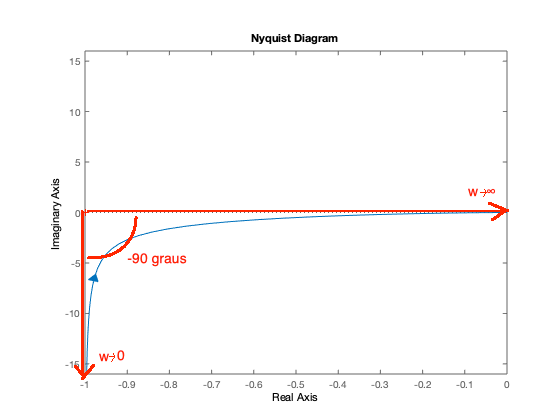

## 1. Verificar a estabilidade usando o critério de Nyquist com gráficos polares (ou de Nyquist).

1.1 Para que valores de ganho esta FT é estável?

g=tf([1 100],poly([0 -1 -10]))

g =
 
        s + 100
  -------------------
  s^3 + 11 s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


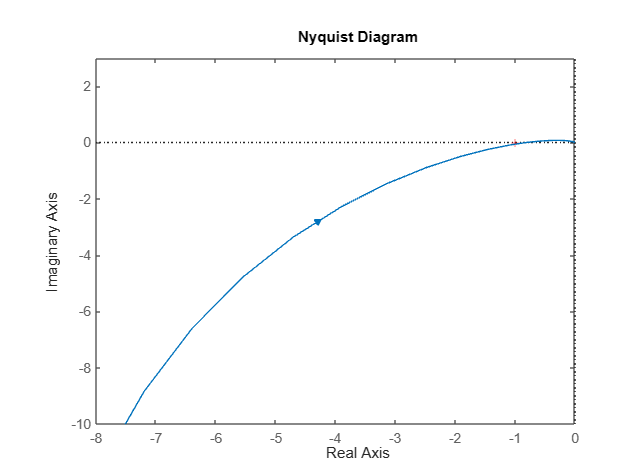

figure;
h=nyquistplot(g);
set(h,'ShowFullContour','off');
ylim([-10 3]);

Resposta:

Para estabilidade fi = 90 graus por aplicação do metodo

Encontrar o ponto antes ou depois de -1 define a estabilidade

K * -0.8 vai ficar a esquerda de -1

O que vai deixar intavel o sistema é o K que vai fazer esse grafico passar a esquerda do -1.

O valor do K que vai deixar o grafico a esquerda do -1.

O gráfico tem que envolver o -1 para deixar instável.

No grádico de bode, quando a freência é 180 graus, equivale ao -1 do gráfico de bode .

É preciso levar esse ponto para o gráfico de magnitudo e verificar onde o ponto que toca o -180 vai tocar a magnitude.

Dessa forma, se esse valor for menor que zero (-1) o gráfico é estavel

Se o gráfico for maior que o zero, então é instável

1.2 Para que valores de ganho esta FT é estável?

g=tf([1 10],[1 0 0])

g =
 
  s + 10
  ------
   s^2
 
Continuous-time transfer function.
Model Properties


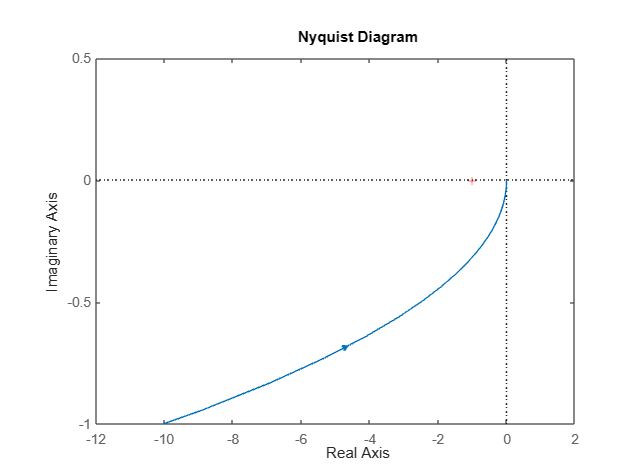

figure;
h=nyquistplot(g);
set(h,'ShowFullContour','off');
ylim([-1 0.5]);

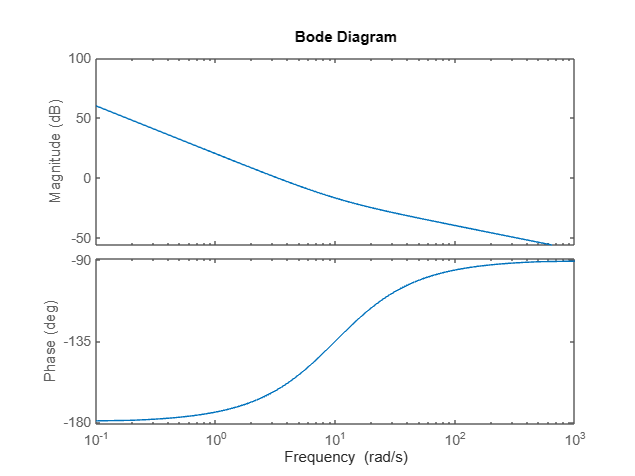

figure;
bode(g)

Resposta:

A margem de ganho é infinito

Esse grafico é estãvel

O calculo do fi deu que ele precisa ser -180 graus

E ele deu 180 graus

A margem de ganho é infinito pq para qualquer valor de fi o gráfico nunca vai envolver o -1

Margem de fase: quando o módulo é 1 (em zero dbs) quanto falta para chegar no 180 graus

1.3 Para que valores de ganho esta FT é estável?

Primeiro tem que encontrar o fi de estabilidade

O Pd e o Pw

g=tf(0.5*[1 3],[1 -1 0])

g =
 
  0.5 s + 1.5
  -----------
    s^2 - s
 
Continuous-time transfer function.
Model Properties


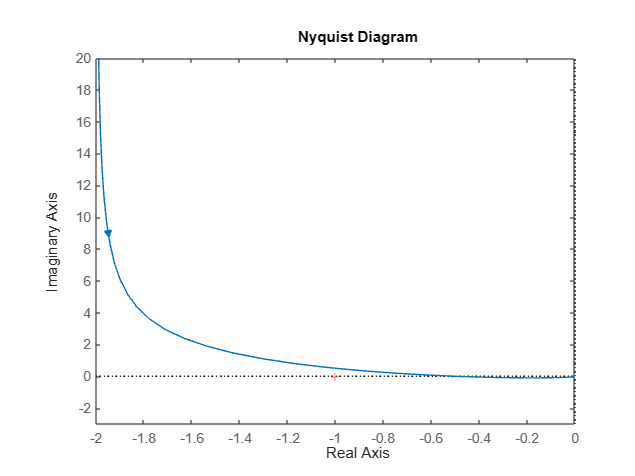

figure;
h=nyquistplot(g);
set(h,'ShowFullContour','off');
ylim([-3 20]);

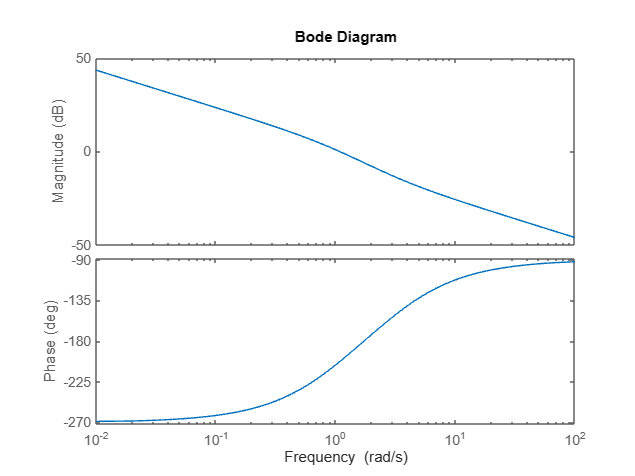

figure;
bode(g)

1.4 Obter o faixa de ganhos K para estabilidade do sistema abaixo.

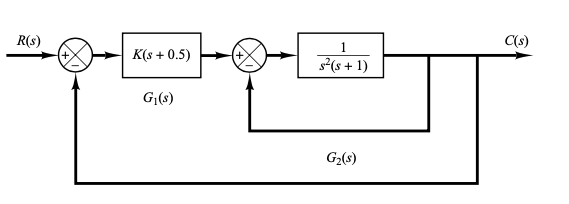

g=tf([1 0.5],[1 1 0 1])

g =
 
     s + 0.5
  -------------
  s^3 + s^2 + 1
 
Continuous-time transfer function.
Model Properties


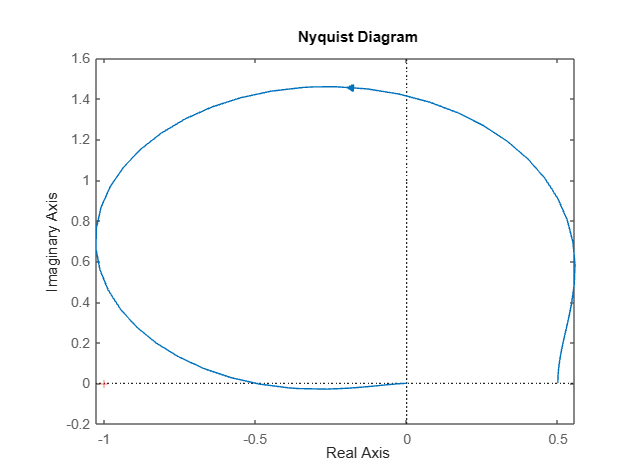

figure;
h=nyquistplot(g);
set(h,'ShowFullContour','off');

Resposta:

1.4 Seja o gráfico de Nyquist mostrado abaixo para uma FT G(s) com 2 polos no SPD, 1 polo na origem, e 1 zero no SPE. Verifique se este sistema é estável em malha fechada.

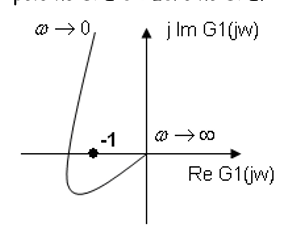

1.5 Seja o gráfico de Nyquist de G(s) mostrado abaixo, desenhado para K=1. Sabendo tratar-se de um sistema de fase mínima, obtenha os valores de K para estabilidade.

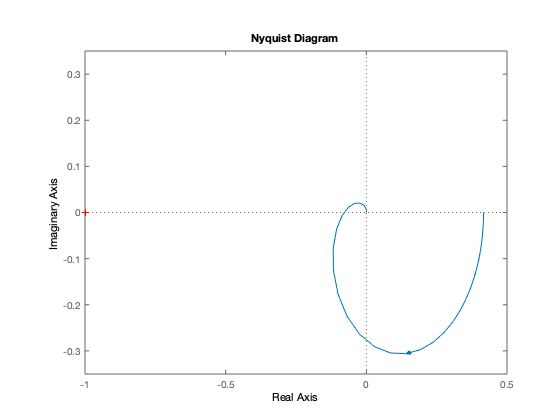

Resposta:

## 2. Estabilidade relativa via gráficos de Bode

2.1 Verifique a margem de fase e de ganho do sistema abaixo. 

g=tf(1,poly(-[0 1 10]));
figure;
bode(g);grid;

Resposta:

2.2 Verifique qual a nova margem de ganho e fase se um ganho K=10 for adicionado à FT.

g=tf(10,poly(-[0 1 10]));
figure;
bode(g);grid;


Resposta:

2.3 Verifique a margem de fase e de ganho do sistema abaixo. 

g=tf(0.5*[1 3],[1 -1 0]);
figure;
bode(g);grid;

2.4 Verifique a margem de fase e de ganho do sistema abaixo. 

g=tf(5,poly(-[1 10]));
figure;
bode(g);grid;


2.5 Seja $G(s)=10\frac{1/p+1}{s(s+1)(s+10)}$ . Avalie o efeito da localização do zero nas margens de fase e ganho.

Relacione estas mudanças com a resposta ao degraus.

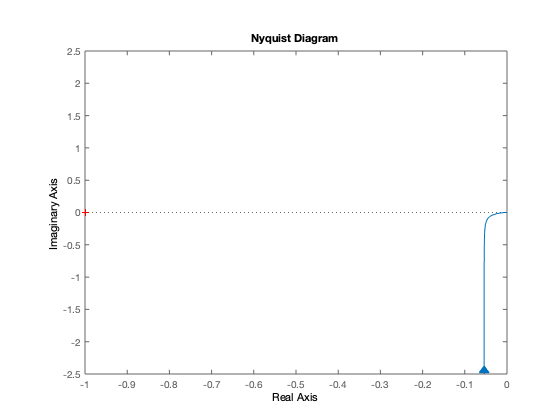

p=0; % escolher um valor de p entre 0 e 100
if p==0
g=tf(K,poly(-[0 1 10]));
else
    g=tf(K*[1/p 1],poly(-[0 1 10]));
end
figure;h=nyquistplot(g);set(h,'ShowFullContour','off');

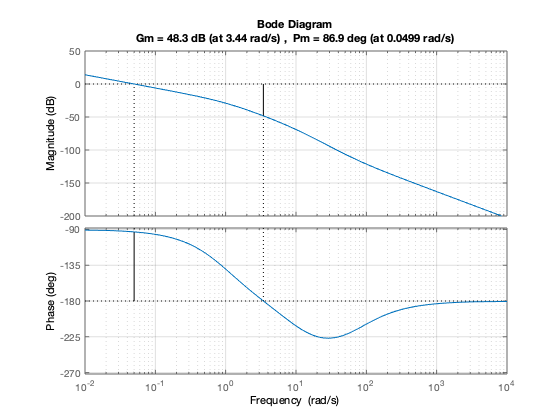

figure;margin(g);grid;

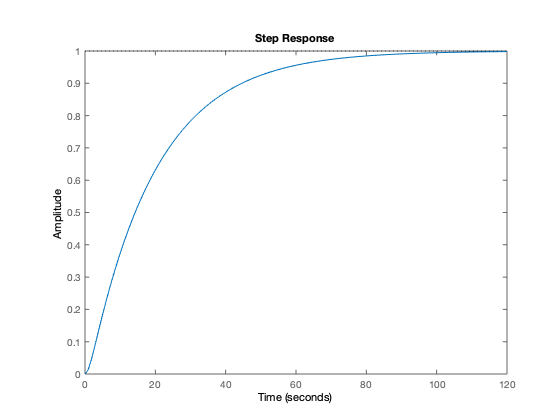

figure;step(feedback(g,1));

2.6 Verifique a estabilidade relativa do sistema cujo gráfico de Bode é mostrado abaixo

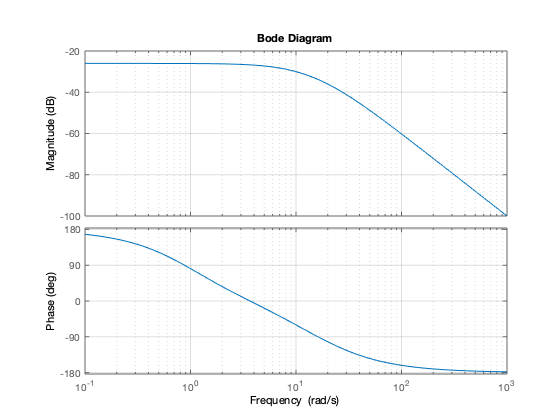

Resposta:

## 3. Sistemas com atraso de tempo

3.1  Obter o faixa de ganhos K para estabilidade do sistema cuja FT de malha aberta é $G(s)=\frac{Ke^{-0.8s}}{s+1}$.

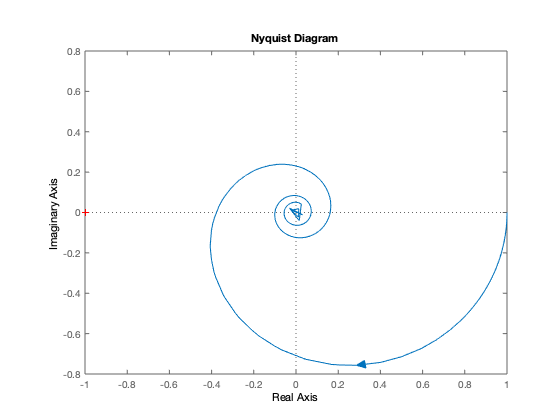

g=tf(1,[1 1], 'InputDelay',0.8);
figure;
h=nyquistplot(g);
set(h,'ShowFullContour','off');

3.1 Avaliar o efeito do atraso de tempo na estabilidade relativa do sistema dado por $G(s)=\frac{Ke^{-ds}}{s+1}$ para $K=0.5$ e para $K=2$.

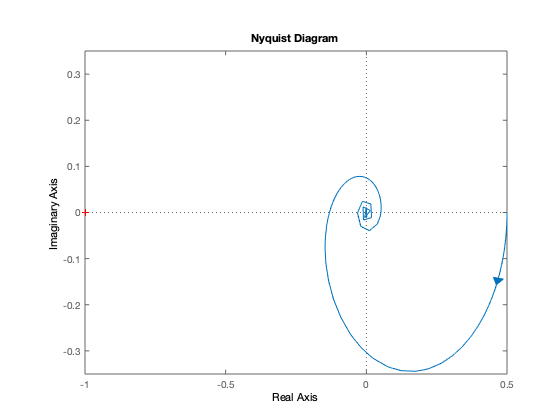

K=0.5; 
d=0; % Escolher um valor de d entre 0 e 1
g=tf(K,[1 1],'InputDelay',d);

figure;h=nyquistplot(g);set(h,'ShowFullContour','off');

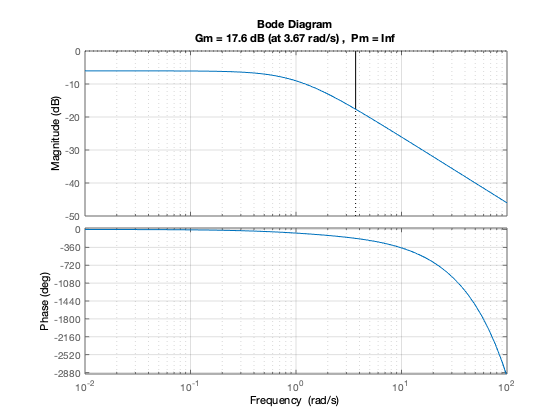

figure;margin(g);grid;

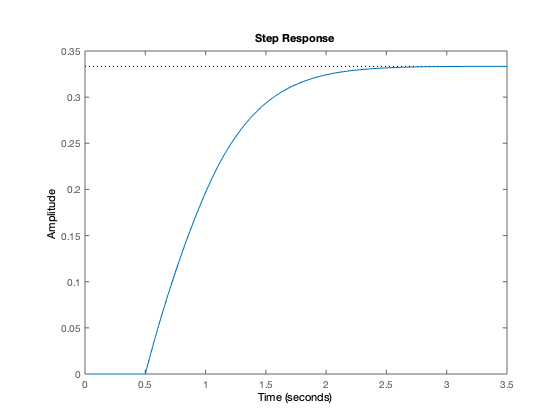

figure;step(feedback(g,1));